# LPF Coefficients

Date Created: 2026-02-26

Last Edited: 2026-08-26

Objective: To find the low pass FIR filter co-efficients using a hamming window

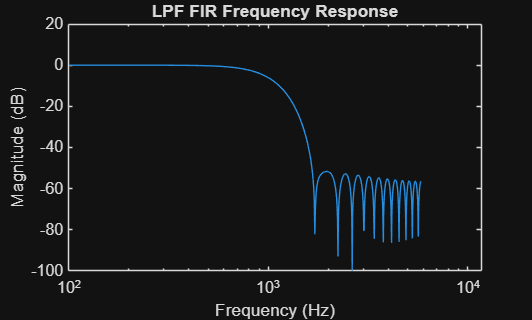

fs = 11.7E3; %sampling frequency in Hz
fc = 1E3;    % cutoff frequency in Hz
L  = 31;    % transition width in Hz

% FIR filter coefficients
b = fir1(L-1, 2*fc/fs, 'low', hamming(L));
a = 1;

fir_coeffs(b);

% plot the frequency response
[h, w] = freqz(b, a);
mag_dB = 20*log10(abs(h));
phase = rad2deg(angle(h));
freq = w*fs/(2*pi);
figure(1)
clf
semilogx(freq,mag_dB)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('LPF FIR Frequency Response')
xlim([100 fs])
hold off